# Wild-type cancer cell line metabolic fluxes for 825 cancer cell lines

## Introduction

This script constructs 825 cancer cell line metabolic models using the eGEM model as the base metabolic model. We will impose the following constraints:

- Gene expression: DNA microarray from the CCLE

- Medium: Medium conditions from the CCLE

- Epsilon2: Coefficients used to add flux into the histone reactions

## Get cancer cell lines that intersect with the global chromatin profiles

Not all 1037 cancer cell lines in the DNA microarray dataset intersect with the global chromatin profiles. We need to filter those out. 

% Load DNA microarray and GCP
load ccle_geneExpression_vars.mat
load CCLE_Proteomics.mat

% Get intersection indicies
[~, ia, ib] = intersect(string(celllinenames_ccle1), string(cell_names));

% Extract intersection data
microarray_cellnames = celllinenames_ccle1(ia);
microarray_data = ccle_expression_metz(:, ia);
microarray_genenames = ccleids_met;

gcp_cellnames = cell_names(ib);
gcp_medium = medium(ib);
gcp_data = proteomics(ib, :);
gcp_culture = cultures(ib, :);
gcp_tissue = tissues(ib, :);

Now that we have intersecting datasets, we can construct wild-type metabolic models for 855 cancer cell lines.

## Compute wild-type metabolic models

Let's now compute wild-type metabolic models. First, we'll load the metabolic model, which is the latest version of the eGEM (05/04/2020).

load 05042020eGEM.mat
model = eGEM; histoneRxnPos = [3755, 3756, 3757, 3758];

We can set up the hyperparameters as the default values.

% Set up hyperparameters for the linear programming section
hyperparams.eps = [];  hyperparams.kap = [];
hyperparams.rho = [];  hyperparams.mode = true;
hyperparams.eps2 = []; hyperparams.pfba = true;
hyperparams.kap2 = [];

Next, let's use the activity coefficient as `1E-3`, which was used in Shen et al., 2019.

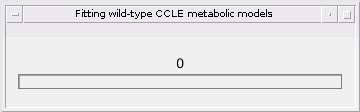

% Compute metabolic models
activityCoef = 1E-3;
wtbr = waitbar(0, '0', 'Name', 'Fitting wild-type CCLE metabolic models');

for i = 1:length(ia)
    constrainedModel = model;
    mediumModel = addMediumConstraints(constrainedModel, string(gcp_medium(i)));
    
    diffExpGenes  = findDiffExpGenes(mediumModel, string(gcp_cellnames(i)));          
    ON_fieldname  = string(strcat('ON_', string(gcp_cellnames(i))));                         
    OFF_fieldname = string(strcat('OFF_', string(gcp_cellnames(i))));
    
    for j = 1:length(histoneRxnPos)
        tmp = mediumModel;
        tmp.c(histoneRxnPos(j)) = activityCoef;
        [WT_CCL, WT_Soln] = CFR(mediumModel, hyperparams, ...
                                diffExpGenes.(ON_fieldname), ...
                                diffExpGenes.(OFF_fieldname));
        grate(i, j) = WT_Soln.x(3743);
        histflux(i, j) = WT_Soln.x(histoneRxnPos(j));
    end
    waitbar(i/length(ia), wtbr, sprintf('%d', i)) 
end

Unrecognized function or variable 'findDiffExpGenes'.

## Save metabolic models and metabolic flux solutions

filename = 'WT_eGEM.mat';
save(filename, '-v7.3');

## Compute correlation between histone flux and CCLE GCP using WT data

First, let's extract the fluxes obtained from the cancer cell line models

ac  = [4, 9, 10, 16, 17, 33]
me1 = [2, 6, 21, 24, 31, 39, 41]
me2 = [3, 7, 22, 28, 42]
me3 = [8, 23]

% Extract metabolic fluxes
for i = 1:length(ia)
    ac_flux(i)  = WT_Soln{i}.x(3752);
    me1_flux(i) = WT_Soln{i}.x(3759);
    me2_flux(i) = WT_Soln{i}.x(3760);
    me3_flux(i) = WT_Soln{i}.x(3761);
end

This is an optional pre-processing step that rescales the values to be between 0 and 1

% Re-scale GCP data using Min-Max scaling
for i = 1:size(gcp_data, 1)
    norm_gcp_data(i, :) = rescale(gcp_data(i, :));
end

% Get individual marker data
norm_acmarks  = norm_gcp_data(:, ac);
norm_me1marks = norm_gcp_data(:, me1);
norm_me2marks = norm_gcp_data(:, me2);
norm_me3marks = norm_gcp_data(:, me3);

% Get individual marker data
acmarks  = gcp_data(:, ac);
me1marks = gcp_data(:, me1);
me2marks = gcp_data(:, me2);
me3marks = gcp_data(:, me3);

% Correlations are not that great
for i = 1:size(acmarks, 2)
    ac_corr(:, i)  = corr(acmarks(:, i),  ac_flux');
end

for i = 1:length(me1)
    me1_corr(:, i) = corr(me1marks(:, i), me1_flux');
end

for i = 1:length(me2)
    me2_corr(:, i) = corr(me2marks(:, i), me2_flux');
end

for i = 1:length(me3)
    me3_corr(:, i) = corr(me3marks(:, i), me3_flux');
end